# Actividad Práctica N°2: Diseño de controladores en variables de estado en tiempo continuo

## Caso de estudio 1. Sistema de tres variables de estado

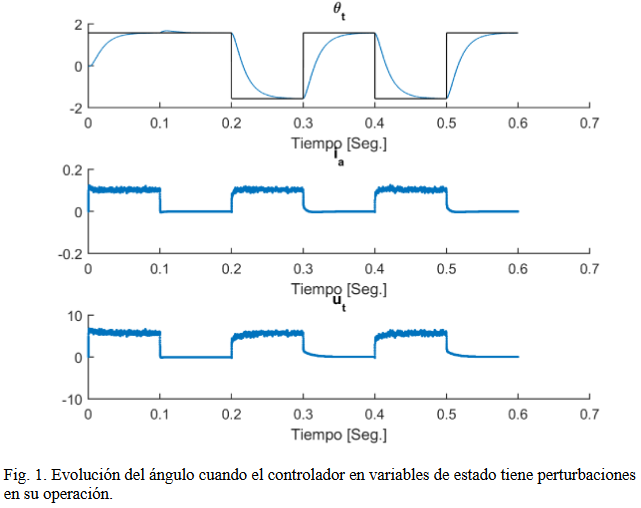

Dadas las ecuaciones del motor de corriente continua con torque de carga $T_L$ no nulo, con los parámetros:

- 
$$L_{\textrm{AA}} =5\;{10}^{-3}$$


- 
$$J=0\ldotp 004$$


- 
$$R_A =0\ldotp 2$$


- 
$$B_m =0\ldotp 005$$


- 
$$K_i =6\ldotp 5\;{10}^{-5}$$


- 
$$K_m =0\ldotp 055$$



$$\frac{{\textrm{di}}_a }{\textrm{dt}}=-\frac{R_A \;}{L_{\textrm{AA}} }i_a -\frac{K_m \;}{L_{\textrm{AA}} }\omega {\;}_r +\frac{1\;}{L_{\textrm{AA}} }v_a$$



$$\frac{d\omega {\;}_r }{\textrm{dt}}=\frac{K_i \;}{J}i_a -\frac{B_m \;}{J}\omega_r -\frac{1\;}{J}T_L$$



$$\frac{d\theta {\;}_t }{\textrm{dt}}=\omega_r$$


- Implementar un sistema en variables de estado que controle el ángulo del motor, para consignas de $\frac{\pi }{2}$ y $-\frac{\pi }{2}$ cambiando cada 2 segundos y que el $T_L$ de $1\ldotp 15\;10{\;}^{-3}$ aparece sólo para $\frac{\pi }{2}$ y para $-\frac{\pi }{2}$ es nulo. Hallar el valor de integración de Euler adecuado. El objetivo es mejorar la dinámica del controlador que muestra la Fig. 1.

- Considerar que no puede medirse la corriente y sólo pueda medirse el ángulo, por lo que debe implementarse un observador. Obtener la simulación en las mismas condiciones que en el punto anterior, y superponer las gráficas para comparar.

Se comienza definiendo las constantes:

Laa = 5e-3;
J = 0.004;
Ra = 0.2;
Bm = 0.005;
Ki = 6.5e-5;
Km = 0.055;

Ahora la representación matricial en variables de estado:

A = [-Ra/Laa -Km/Laa 0; Ki/J -Bm/J 0; 0 1 0]

A =   -40.0000  -11.0000         0
    0.0162   -1.2500         0
         0    1.0000         0


B = [1/Laa 0; 0 -1/J; 0 0]

B =    200     0
     0  -250
     0     0


C = [0 0 1]

C =      0     0     1


D = [0 0]

D =      0     0


Se obtiene la función de transferencia para el torque:

sys = ss(A,B,C,D)

sys =
 
  A = 
            x1       x2       x3
   x1      -40      -11        0
   x2  0.01625    -1.25        0
   x3        0        1        0
 
  B = 
         u1    u2
   x1   200     0
   x2     0  -250
   x3     0     0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.


GTheta = tf(sys)

GTheta =
 
  From input 1 to output:
            3.25
  -------------------------
  s^3 + 41.25 s^2 + 50.18 s
 
  From input 2 to output:
        -250 s - 1e04
  -------------------------
  s^3 + 41.25 s^2 + 50.18 s
 
Continuous-time transfer function.
Model Properties


Se puede ver que la función de transferencia está dada en forma de matriz, ya que se está ante un sistema del tipo MIMO.

La matriz de controlabilidad del sistema es:

M = [B(:,1) A*B(:,1) A^2*B(:,1)]

M = 1.0e+05 *

    0.0020   -0.0800    3.1996
         0    0.0000   -0.0013
         0         0    0.0000


Para comprobar controlabilidad:

if(rank(M) == rank(A))
    disp('Sistema Controlable')
else
    disp('Sistema No Controlable')
end

Sistema No Controlable


El polinomio carácterístico del sistema es:

pA = poly(A)

pA =     1.0000   41.2500   50.1788         0


Ahora, para obtener el controlador. Haciendo uso de Sylvester:

W = [pA(3) pA(2) 1; pA(2) 1 0; 1 0 0]

W =    50.1788   41.2500    1.0000
   41.2500    1.0000         0
    1.0000         0         0


T = M*W

T =          0  250.0000  200.0000
         0    3.2500         0
    3.2500         0         0


Los autovalores de la matiz A son los polos a lazo abierto del sistema, ya que el polinomio característico es la ecuación característica, por ello, se tiene:

eig(A)

ans =          0
   -1.2546
  -39.9954


Para mejorar la respuesta del sistema, se introducen polos para lazo cerrado que estén alejados por lo menos una decada, de forma de obtener transitorios más cortos. Además, es posible ver que existe un polo positivo, lo que implica que a priori el sistema es inestable.

p1 = -45;
p2 = -20;
p3 = -1;
poles = [p1 p2 p3];

Con estos nuevos polos, se pretende armar una nueva función $\alpha \;$:

alphaf = poly(poles)

alphaf =      1    66   965   900


Ahora se hace uso de la función derivada de Cayley Hamilton, de la siguiente forma:

K = (fliplr(alphaf(2:end)-pA(2:end))*inv(T))

K =     0.1237  271.9642  276.9231


Con los siguientes polos a lazo cerrado, que deberían ser los planteados anteriormente:

sysT = A-B(:,1)*K;
eig(sysT)

ans =   -45.0000
  -20.0000
   -1.0000


Ahora entonces se obtiene G:

G = -inv(C*inv(sysT)*B(:,1))

G = 276.9231

Para hallar el período de integración por Euler entonces se obtiene lo siguiente:

tr = log(0.95)/min(eig(sysT))

tr = 0.0011

El tiempo de integración debe ser menor al $t_R$ calculado, se toma entonces $1\;{10}^{-6}$.

Ahora, obtenido el período de integración por Euler, se procede a simular el sistema. Para ello, primero se declaran todas las variables de interés que serán utilizadas para la simulación.

h = 1e-6;
T = 20;
Kmax = T/h;
t = linspace(0,T,Kmax);
thetaRef = pi/2;
torqueRef = 1.15e-3;
ia(1) = 0;
theta(1) = 0;
omega(1) = 0;
omegaP(1) = 0;
reference(1) = thetaRef;
xop = [0;0;0];
x = [ia(1); omega(1); theta(1)];
stateVector = [ia(1);omega(1);theta(1)];
u(2,:) = 0;
index = 0;

Ahora, la simulación propiamente dicha.

for i = 1:Kmax-1
    index = index+h;
    if(index < 10)
        TL = torqueRef;
        thetaInput = thetaRef;
    else
        TL = 0;
        thetaInput = -thetaRef;
    end
    reference(i) = thetaInput;
    u(:,i) = [-K*stateVector+G*reference(i);TL];
    xp = A*(x-xop)+B*u(:,i);
    x = x+xp*h;
    Y = C*x+D*u(:,i);
    ia(i+1) = x(1);
    omega(i+1) = x(2);
    theta(i+1) = x(3);
    stateVector = [ia(i);omega(i);theta(i)];
end
u(:,i+1) = u(:,i);
u = u(1,:);
reference(i+1) = reference(i);

Se grafica entonces la salida del sistema.

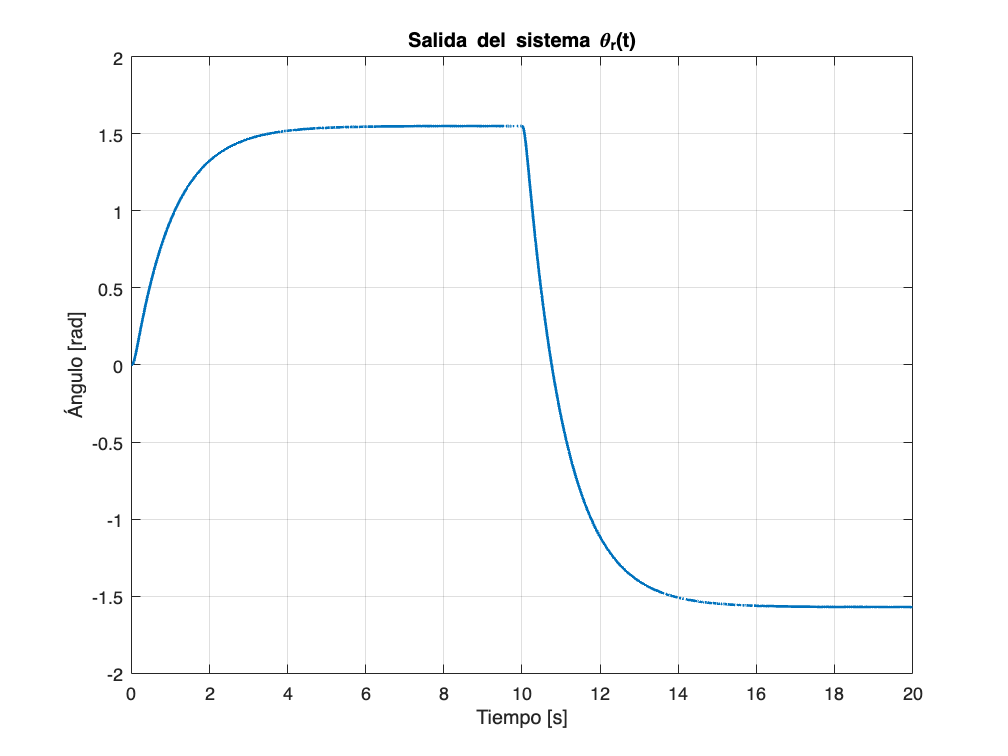

plot(t,theta,'LineWidth',1.5);
title('Salida del sistema \theta_r(t)')
xlabel('Tiempo [s]')
ylabel('Ángulo [rad]')
grid

Luego, la figura siguiente muestra la acción de control.

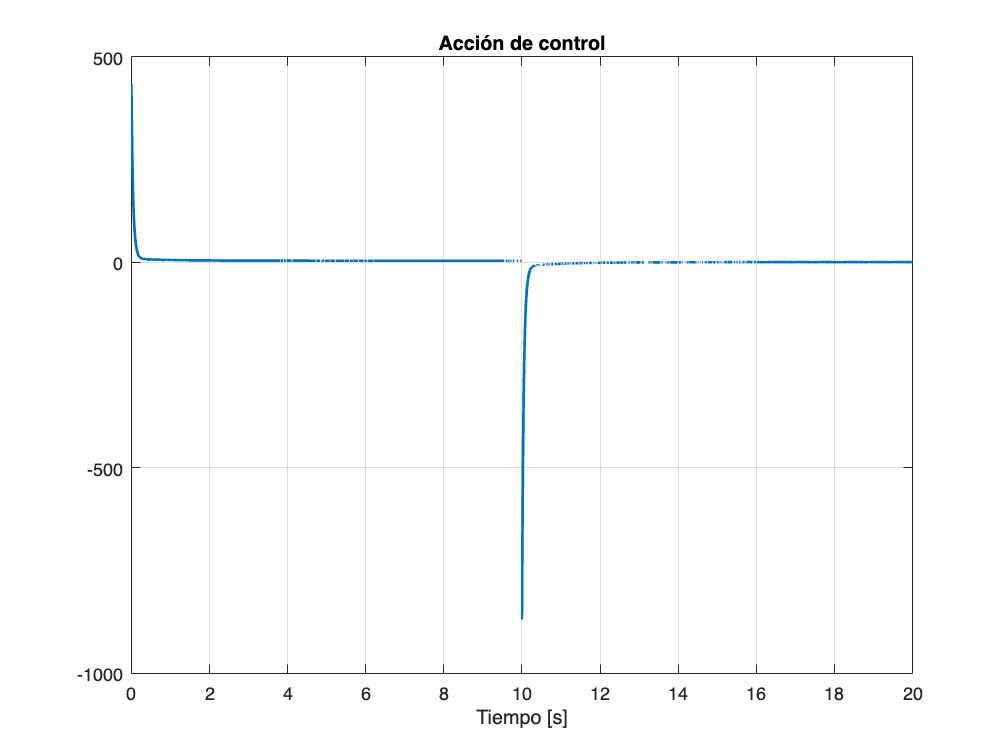

plot(t,u,'LineWidth',1.5);
title('Acción de control')
xlabel('Tiempo [s]')
grid

La corriente en el sistema es:

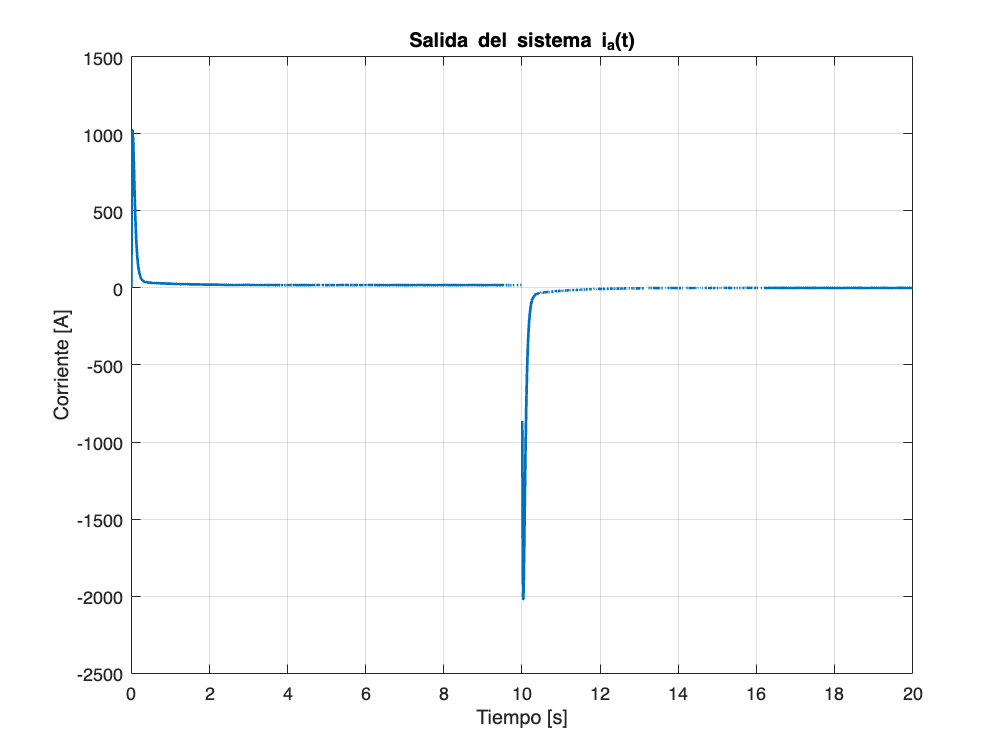

plot(t,ia,'LineWidth',1.5);
title('Salida del sistema i_a(t)')
xlabel('Tiempo [s]')
ylabel('Corriente [A]')
grid

Ahora, para implementar el observador, se plantean las siguientes matrices, iguales a las usadas en el inciso anterior traspuestas. Y, para observar la corriente, es necesario modificar la matriz C, por eso:

Ao = A'

Ao =   -40.0000    0.0162         0
  -11.0000   -1.2500    1.0000
         0  250.0000         0


Bo = C'

Bo =      0
     0
     1


Co = B'

Co =    200     0     0
     0  -250     0


Se desplazan los polos del observador una década con respecto a los del sistema controlado a lazo cerrado.

obsPoles = poles*10

obsPoles =   -450  -200   -10


La función $\alpha$ del observador será:

alphaO = poly(obsPoles)

alphaO =            1         660       96500      900000


Se requiere ahora la matriz de controlabilidad para el sistema dual, 

Mdual = [Bo Ao*Bo Ao^2*Bo]

Mdual =          0         0    0.0162
         0    1.0000   -1.2500
    1.0000         0  250.0000


Ahora, se debe obtener T para el observador, eso se hace al igual que en el caso anterior.

To = Mdual*W

To =     0.0162         0         0
   40.0000    1.0000         0
   50.1788   41.2500    1.0000


La matriz K para el observador es:

Ko = (fliplr(alphaO(2:end)-pA(2:end))*inv(To))'

Ko = 	1.0e+08 *

   -1.2111
    0.0007
    0.0000


Y sus polos son:

eig(A-Ko*C)

ans =   -10.0000
 -200.0000
 -450.0000


Ahora, para comparar el comportamiento de la corriente con y sin obsrevador.

h = 1e-6;
T = 20;
Kmax = T/h;
t = linspace(0,T,Kmax);
thetaRef = pi/2;
torqueRef = 1.15e-3;
ia(1) = 0;
theta(1) = 0;
omega(1) = 0;
omegaP(1) = 0;
reference(1) = thetaRef;
xop = [0;0;0];
x = [ia(1); omega(1); theta(1)];
xo = [0 0 0]';
stateVector = [ia(1);omega(1);theta(1)];
u(2,:) = 0;
index = 0;
TL = torqueRef;
for i = 1:Kmax-1
    index = index+h;
    if(index < 10)
        TL = torqueRef;
        thetaInput = thetaRef;
    else
        TL = 0;
        thetaInput = -thetaRef;
    end
    reference(i) = thetaInput;
    u(:,i) = [-K*stateVector+G*reference(i);TL];
    xp = A*(x-xop)+B*u(:,i);
    x = x+xp*h;
    Y = C*x+D*u(:,i);
    ia(i+1) = x(1);
    omega(i+1) = x(2);
    theta(i+1) = x(3);
    yO = C*xo;
    y = C*stateVector;
    xPrev = A*xo+B*u(i)+Ko*(y-yO);
    xo = xo+xPrev*h;
    stateVector = [ia(i);omega(i);theta(i)];
end
plot(t,xo(3,:),'LineWidth',1.5)

Error using plot
Vectors must be the same length.

xlabel('Tiempo [seg]')
title('Salida de corriente por observador')

## Caso de estudio 2. Sistema no lineal de cuatro variables de estado

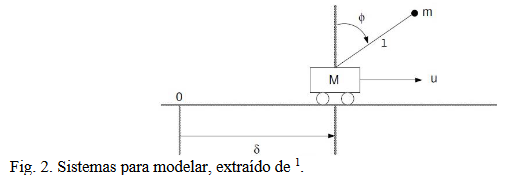

Para el caso del esquema del péndulo invertido de la figura 2, donde el modelo es:


$$\left\lbrace \begin{array}{ll}
\left(M+m\right)\ddot{\delta +\textrm{ml}\ddot{\phi \;} \cos \left(\phi \;\right)-\textrm{ml}\dot{\phi {\;}^2 \textrm{sen}\left(\phi \right)+F\dot{\;\delta \;} =u} }  & \;\\
l\ddot{\phi \;} -\textrm{gsen}\left(\phi \;\right)+\ddot{\delta \;} \cos \left(\delta \;\right)=0 & \;
\end{array}\right.$$


Con las variables de estado $x={\left\lbrack \delta \;\;\dot{\;\delta \;} \;\;\phi \;\;\;\dot{\;\phi \;} \right\rbrack }^T$, y los valores de los coeficientes:

- 
$$m=0\ldotp 1$$


- 
$$F=0\ldotp 1$$


- 
$$l=1$$


- 
$$g=9\ldotp 8$$


- 
$$M=1\ldotp 5$$


Determinar $\Delta \;t$ y el tiempo de simulación adecuados.

- Calcular un controlador que haga evolucionar al péndulo en el equilibrio inestable, partiendo de una condición inicial nula en el desplazamiento y termine en -10 metros manteniendo la vertical. Determinar el ángulo máximo que puede alejarse de la vertical en t=0 para que el sistema cumpla el objetivo de control.

- Incorporar un observador para el caso en que sólo puedan medirse el desplazamiento $\delta \;$ y el ángulo $\phi \;$, repetir las simulaciones para las condiciones anteriores y graficar los resultados en gráficas superpuestas.

- Calcular un controlador que haga evolucionar al péndulo en el equilibrio estable, partiendo de una condición inicial nula en el desplazamiento y el ángulo en $\pi \;$ que termine en 2 metros evitando las oscilaciones de la masa m, considerando que es una grúa. Una vez que $\delta =2$ modificar a m a un valor 10 veces mayor y volver al origen evitando oscilaciones.

- Incorporar un observador para el caso en que sólo pueden medirse el desplazamiento $\delta \;$ y el ángulo $\phi \;$, repetir las simulaciones para las condiciones anteriores y graficar los resultados en gráficas superpuestas para el equilibrio estable.

Primero se definen las constantes:

m = 0.1;
F = 0.1;
l = 1;
g = 9.8;
M = 1.5;

Ahora, las matrices:

A = [0 1 0 0; 0 -F/M -m*g/M 0; 0 0 0 1; 0 F/(l*M) g*(M+m)/(l*M) 0]

A =          0    1.0000         0         0
         0   -0.0667   -0.6533         0
         0         0         0    1.0000
         0    0.0667   10.4533         0


B = [0; 1/M; 0; -1/(l*M)]

B =          0
    0.6667
         0
   -0.6667


M = [B A*B A^2*B A^3*B]

M =          0    0.6667   -0.0444    0.4385
    0.6667   -0.0444    0.4385   -0.0583
         0   -0.6667    0.0444   -6.9719
   -0.6667    0.0444   -6.9719    0.4938


Ahora, para el cálculo del LQR:

R = 100;
Q = diag([0.002 1 0.1 0.01])

Ahora, se debe construir el Hamiltoniano:

H = [A -B*inv(R)*B'; -Q -A']
[n,va] = size(H);
[V,D] = eig(H);
M12 = [];

Se crearon variables auxiliares con el fin de no tener que usar seguido métodos como eig() o size(). A continuación, la simulación propiamente dicha.

for (i = 1:n)
    if(real(D(i,i)) < 0)
        M12 = [M12 V(:,i)];
    end
end
M1 = M12(1:n/2,:);
M2 = M12(n/2+1:end,:);

Ahora, la solución de la ecuación de Ricatti para tiempo continuo:

P = real(M2*inv(M1))

La matriz de controlabilidad:

K = inv(R)*B'*P

El estado del sistema se describe mediante la matriz states, y, se deben inicializar los 

states = [p(1);]